# Pressure, Velocity, Energy and Power

[⇦ Return to the navigation page](matlab:run("Navigation.mlx"))

In fluid dynamics, understanding the link in between pressure, velocity, energy and power is essential because they are the driving mechanism of fluid flow. Pressure is closely relate to the forces exherted by the fluid, velocity measure the speed and direction of the fluid, energy is a measure of the ability of a fluid to do work, and power is a measure of the rate at which energy is transfered. In this script we will explore how these concept are related, interact and how critical they are in the design and analysis of fluid systems such as pumps, pipelines, and hydroelectric power plants.

[Catchy Image]

## **Before you get started**

This live script is intended to be used with the code visible and output inline. On the **View** tab of the MATLAB Toolstrip, in the **View** section, select **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

 Interacting with this live script will build somgit e familiarity with MATLAB as concepts and commands are introduced together. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if run out of order.

The    and   icons refer to two different types of interactive activities that you will find in this script. The    usually indicates an interaction where you will explore the visualization of some concept introduced in this script. The  interactions are designed to challenge your understanding of those concepts and may be used for grading and completion checks by your professor.

## What are pressure, velocity & energy?

### Pressure

When a fluid is enclosed in a container, the fluid exert a certain force on the wall of this container. On a microscopic scale, the fluid molecules are impacting and bouncing back from the wall. It is those impacts that, added altogether among a very large amount of molecule, are thought of as pressure. The pressure $p$, is a scalar quantity that exist in the whole fluid domain, refer to the force per unit of surface that the fluid is to its neighbors. The SI unit of pressure is the Pascal (Pa), named after the [Blaise Pascal](https://en.wikipedia.org/wiki/Blaise_Pascal), a French mathematician and physist from the XVII century.

  **Try.** Visualize pressure

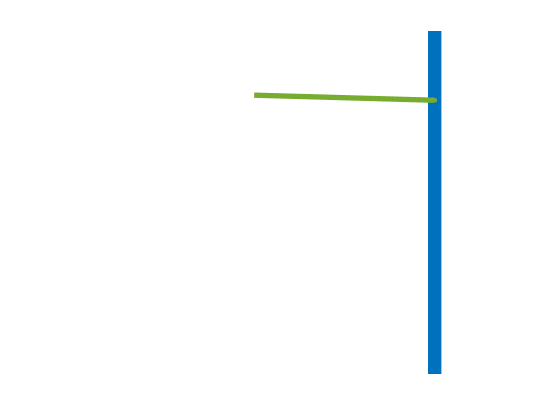

plotPressure()

  **Try.** Create a unit system and explore the information about Pascal 

units = symunit;
Pascals = units.Pa;
unitInfo(Pascals)


pascal - a physical unit of pressure. ['SI']

Get all units for measuring 'Pressure' by calling unitInfo('Pressure').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.



  **Try.** Following the suggestions from the previous section, get all the units of pressure supported in MATLAB®

unitInfo("Pressure")


All units of dimension 'Pressure':

at - technical atmosphere
atm - standard atmosphere
Ba - barye 
bar - bar
cmH2O - centimeter of water (conventional)
cmHg - centimeter of mercury (conventional)
ftH2O - foot of water (conventional)
ftHg - foot of mercury (conventional)
inH2O - inch of water (conventional)
inHg - inch of mercury (conventional)
ksf - kip per square foot
ksi - kip per square inch
mH2O - meter of water (conventional)
mHg - meter of mercury (conventional)
mmH2O - millimeter of water (conventional)
mmHg - millimeter of mercury (conventional)
Pa - pascal ['SI']
psf - pound force per square foot
psi - pound force per square inch
pz - pieze
Torr - torr

Get the base SI units of any unit above by calling rewrite(<unit>,'SI').
SI units accept all SI prefixes. For details, see SI Unit Prefixes List.


As you can see, there is a lot of different units for pressure, each field or discipline tends to use different units because they might be more intuitive for them. 

 **Exercise. **Use [`unitConversionFactor`](https://www.mathworks.com/help/symbolic/unitconversionfactor.html) to compute the conversion factor between bar to Pa, atm to Pa, bar to psi and atm to psi

bar2Pa = unitConversionFactor(units.bar,units.Pa)

$$bar2Pa = 100000$$

atm2Pa = unitConversionFactor(units.atm,units.Pa)

$$atm2Pa = 101325$$

bar2psi = unitConversionFactor(units.bar,units.psi)

$$bar2psi = 14.5038$$

atm2psi = unitConversionFactor(units.atm,units.psi)

$$atm2psi = 14.6959$$

 **Exercise. **Use [`rewrite`](https://www.mathworks.com/help/symbolic/rewrite.html?searchHighlight=rewrite&s_tid=srchtitle_rewrite_1) and [`baseUnits`](https://www.mathworks.com/help/symbolic/baseunits.html?s_tid=doc_ta) to first convert Pascals in the base SI units, and then into N and m.

Pascals = rewrite(Pascals, baseUnits("SI"))

$$Pascals = \frac{\mathrm{kg}}{m\,s^{2}}$$

Pascals = rewrite(Pascals, [units.m units.N])

$$Pascals = \frac{N}{m^{2}}$$

 **Reflect**. Units of pressure such as Pascals correspond to Newton per square meter, wich correspond to unit of force per unit of surface.


$$F=P S$$


### Energy 

Energy in a fluid refers to the ability of a fluid to do work. It can take various forms, such as kinetic energy, which is associated with the motion of the fluid particles, or potential energy, wich is associated with the position of the fluid particles or its pressure. 


$$dE = Fdx$$


**Kinetic Energy:**

**Potential Energy of Pressre:**

syms p S
dE = p*S*dx
dx =0.5;
figure
x = [0 dx 0 0 0 0; 0 dx dx dx dx dx; 0 dx dx dx dx dx; 0 dx 0 0 0 0];
y = [1  1 0 0 1 0; 0  0  0  0 1 0; 0  0  1  1 1 0; 1  1 1 1 1 0];
z = [1  1 1 0 0 0; 1  1  1  0 0 0; 0  0  1  0 1 1; 0  0 1 0 1 1];  
c = [0  0 1 1 2 3; 0  0  1  1 2 3; 0  0  1  1 2 3; 0  0 1 1 2 3];
fill3(x,y,z,c,FaceAlpha=0.5)
xlabel('x')
ylabel('y')
zlabel('z')
ylim([0 1])
zlim([0 1])
xlim([0 2])
axis equal
syms dV
dE = subs(dE, S*dx, dV)

Potential energy: $dE_\text{gravity}$


$$dE = Fdx$$



$$E=\int Fdx$$


### Power

- Power in a fluid refers to the rate at which energy is transferred. It is typically measured in unierts of energy per unit time, such as Watts (W) or horsepower (hp).


$$P=\frac{dE}{dt}$$


### **Application: Wind turbine**

Let's dive in the case of a wind turbine of surface S. 

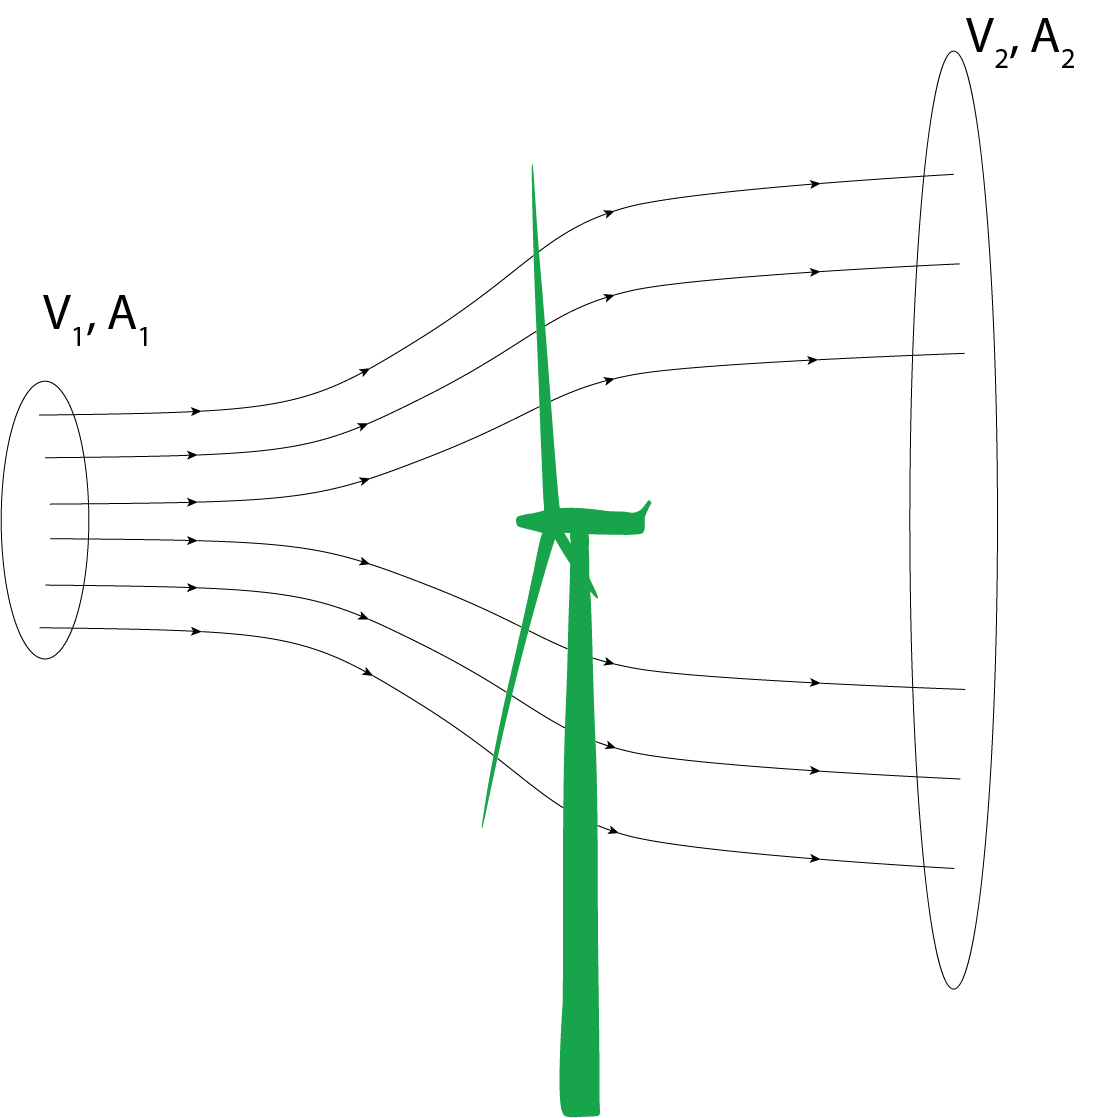

We consider the control volume as describe as in the previos figure. All the mass flow coming in the control volume volume through the surface A, must exit the control volume through surface B. Therefore we can write the following mass flow equilibrium:


$$\rho S_A v_A = \rho S_B v_B = \rho S_t v_t = \dot{m}$$


syms rho S_A S_B S_t v_A v_B v_t
m_dot = rho*S_t*v_t

where $\rho$ is the density, $(A_A,A_B,A_t)$ are the arar of surface A, B and the area of the turbine, and $(v_A,v_B,v_t)$ are the velocity of the flow through the surface A, B and the turbine itself. We consider the density constant through the turbine and therefore end up with the following relation:


$$ S_A v_A = S_B v_B = S_t v_t$$


**What is the force on the wind turbine?**


$$\underbrace{\frac{\partial}{\partial t}\int_{CV}\rho\vec{u} \; dV}_\text{Acceleration}
+
\underbrace{\int_{CS}(\vec{u}\cdot\vec{n})\rho\vec{u} \; dS}_\text{Thrust}
=
\sum\vec{F}$$


We are considering the flow to be at steady-state, so the derivative with respect to time is equal to 0. There is no radial flow, so all the air entering the turbine upstream is exiting the turbine downstream. Therefore, we are left with:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
+
\int_\text{downstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
=
\vec{F}_\text{turbine\rightarrow air}$$


The upstream term can be expressed as:


$$\int_\text{upstream}(\vec{v}\cdot\vec{n})\rho\vec{v} \; dS
=
-\dot{m}v_1$$


 **Exercise. **Complete the expression of $\vec{F}_\text{turbine\rightarrow air}$ in `F_ta`.

F_ta = - m_dot*v_A + m_dot*v_B
F_at = simplify(- F_ta)

**What is the power in fluid going through A?**


$$dE = F dx$$



$$P = \frac{dE}{dx} = F\frac{dx}{dt} = Fv$$


P_at = simplify(F_at * v_t)

**What equilibrium of power can be written?**


$$P_\text{air\rightarrow turbine} = P_1 - P_2$$


 **Exercise. **Write power balance:

P_A = 1/2*m_dot*v_A^2;
P_B = 1/2*m_dot*v_B^2;
PowerBalance = P_at == P_A - P_B

 **Exercise. **Solve

vS = solve(PowerBalance, v_t)
vS = vS(2)

 **Exercise. **Solve

P_at = subs(P_at,v_t,vS)

 **Exercise. **Solve

P_0 = 1/2*rho*S_t*v_A^3;

 **Exercise. **Solve

% Declare the efficient eta = P_at/P_0
eta = P_at/P_0
% Substitute v_B by x*v_A, this should rewrite the equation as a function
% of x = v_B/v_a
eta = simplify(subs(eta, v_B, x*v_A))

% Plotting function
fplot(x,100*eta,[0 1])
xlabel("$x=\frac{v_2}{v_1}$",Interpreter="latex")
ylabel("\eta (%)")
title("Efficiency of wind turbine")

## Bernoulli's Principle

## Definition

The Bernoulli equation is a fundamental tool of fluid dynamisist that describes the relationship between pressure, velocity and elevation change in the fluid. This equation is named after the Swiss mathematician, Daniel Bernoulli, who first formulated it in 1738. The Bernoulli equation states that the total energy of a fluid system is constant along a streamline:


$$P+
\frac{1}{2}\rho v^2+
\rho g h= \text{Constant} \qquad(\star)$$


  **Try. **Check if density is consistent with pressure?

sympref('FloatingPointOutput',true);
units = symunit;
test = units.Pa == units.kg/units.m^3*(units.km/units.h)^2
checkUnits(test)

 **Exercise. **Check that all three terms in $(\star)$ are consistent and compatible in units

test1 = units.Pa == 0.5*units.kg/units.m^3*(units.m/units.s)^2;
test2 = units.Pa == units.kg/units.m^3*units.m/units.s^2*units.m;
checkUnits(test1)
checkUnits(test2)

where P represents the pressure of the fluid, $\rho$ its density, $v$ its velocity, $g$ gravitational acceleration and $h$ the elevation. From a non-expert point of view, the conservation of "energy" promised by the definition is not evident. In order to highlight the energy term, we can multiply both side of $(\star)$ by the volume $V$ (careful with the definition of the fluid's velocity and its volume $v \neq V$):


$$PV+
\frac{1}{2}\rho V v^2+
\rho V g h= \text{Constant} \qquad(\star)\times V$$


with $\rho V = m$, the fluid mass, we obtain:


$$PV+
\frac{1}{2}mv^2+
m g h= \text{Constant} \qquad(\star)\times V$$


- $PV$    is the pressure potential energy

- $\frac{1}{2}mv^2$    is the kinetic energy

- $mgh$    is the gravitational potential energy

So the $(\star)$ is in fact the conservation of the total energy along a stream line. We should now apply the Bernoulli equation along a streamline of a free flowing fluid.

  **Try.** Use the slider below to visualize a streamline in between point A and point B of a fluid flow with an elevation difference.

dh = 9;
vA = 8;
vB = 14;
rho = 1000;
plotStreamline(dh, vA, vB, rho)

The fluid is considered : 

- incompressible ( $\rho=\text{Constant}$ )

- at point A, it has a velocity $v_a$, pressure $P_a = 101,325$ Pa, and its elevation 0 m

- at point B, it has a velocity $v_b$, pressure $P_b$, and its elevation is `dh` m

syms P_A v_A P_B v_B g rho
u = symunit;
g = 9.81*u.m/u.s^2
dh = dh*u.m
P_A = 101325*u.Pa

  **Try.** Select the fluid:

rho = 1000*u.kg/u.m^3

   **Exercise. **Write the total energy at point A as in $(\star)$ and store the results in `E_A`

E_A = P_A + 1/2*rho*v_A + rho*g*0

 **Exercise. **Write the total energy at point B as in $(\star)$ and store the results in `E_B`

E_B = P_B + 1/2*rho*v_B + rho*g*dh

 **Exercise. **Write the equilibrium along the streamline

Eqn = E_B == E_A

 **Exercise. **Explore the following scenario

    1. The velocity is constant ( $v_A=v_B$ ), how does the pressure evolves from A to B depending the on the elevation change?

P_B = solve(Eqn,P_B)

    2. The elevation change are negligeable ( $\Delta h = 0$ ), how does the velocity evolves depending on the pressure change from A to B?

    3. Fuid has constant velocity, dh is positive

The Bernoulli equation $(\star)$ is often writen in the different form, called the hydraulic head form:


$$\frac{P}{\rho g} + \frac{V^2}{2 g} + h = H_0=\text{Constant}$$


The equation stays the same in nature, but the different term are all writen in unit of length instead of being writen in unit of pressure. This form is used in the case of hydraulic flow (flow of water) where the density of the fluid is high and any change in elevation impact the flow. While dealing with gases, the $(\star)$ is preferred as the effect of gravity are often neglected.

Because all of the term in $(\star)$ are dimensionally equivalent to a pressure, we are defining different pressures:

- $P$ is the static pressure.

- $\frac{1}{2}\rho U^2$    is the dynamic pressure, it is pressure that is exerted by the fluid dur to its motion. It is also known as "impact pressure". 

[Image of someone taking a shower] vs [someone impacted by a jet]

- $\rho g h$ is the hydrostatic pressure

The total pressure is defined as the sum of the static, dynamic and hydrostatic pressure:


$$P_\text{total} = P + \frac{1}{2}\rho U^2 + \rho g h$$


Therefore, Bernoulli's equation can be read as the conservation of total pressure along a streamline. Finally, the stagnation pressure is defined as:


$$P_\text{stagnation} = P + \frac{1}{2}\rho U^2$$


The stagnation pressure is equivalent to the pressure that the fluid would have if it came to "stagnation" (a.k.a. $U=0$). It is obtained from applying $(\star)$ as:


$$ P + \frac{1}{2}\rho U^2 = P_\text{stagnation} + \frac{1}{2}\rho 0^2$$


XXX Plot free flow again, next to pressure plot along x, P_tot, 

### **Application: Pitot tube**

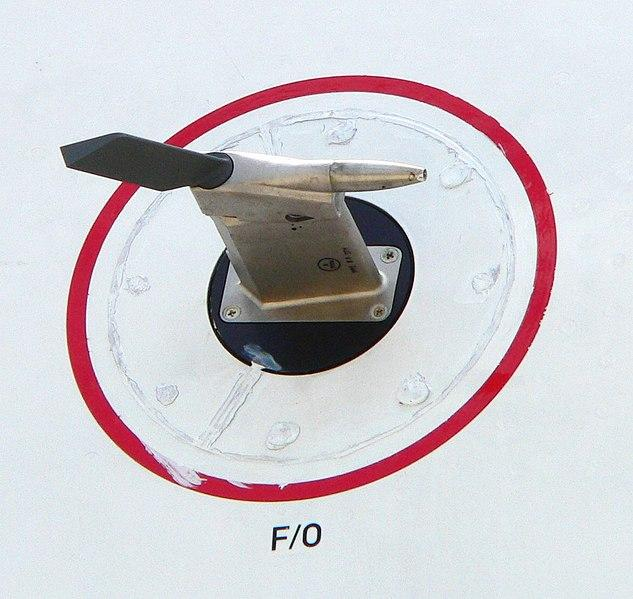

figure
axis equal
axis off
x = [0 1.5   1.5    0  0.15  1.6 1.6 0.35 0.35  1.5   1.5   0.3   0.3 0.15];
y = [0 0   -0.1 -0.1 -0.2 -0.2 0.1  0.1  0.075 0.075 0.025 0.025 0.1  0.1] + 0.05;
patch(x,y,'b',"FaceAlpha",0.3)
hold on
scatter(-0.3,0,30,'filled',"r")
scatter(1.5,0,30,'filled',"r")
line([-0.3 1.5],[0 0])
hold off

Exercise. Identify the pressure in measure at point A and point B

Exercise. Express the free-stream velocity as a function of $\Delta p = p_t - p_s$

% Declare the parameter of the problem
syms pt ps rho u dp
% Define the equation defining the relation between pt and ps
eqn = pt == ps + (rho*u^2/2);
% Solve this equation for u, the velocity
u = solve(eqn, u)
% Select the correct solution
u = simplify(u(1)) 
% substitue pt-ps for dp
u = subs(u, pt-ps, dp)
% Plot the velocity based on the measure difference of pressure

### **Application: Lift generation around airfoil**

**Used for Cessna 172R**

[lc,lu,ll] = NACAXXXX(12,2,40);
CruiseSpeed = 135 * units.kts;
CruiseSpeed = unitConvert( CruiseSpeed, units.m/units.s)
rho = 1.14 * units.kg/units.m^3;
P_inf = 101325* units.Pa;
q_inf = 1/2*rho*CruiseSpeed^2;
P_tot = simplify(P_inf + q_inf)
AirfoilLength = 1*units.m;
transitTime = AirfoilLength / CruiseSpeed
v_upper = lu*units.m / transitTime
v_lower = ll*units.m / transitTime
q_upper = 1/2*rho*v_upper^2
P_upper = simplify(P_tot - q_upper)
q_lower = 1/2*rho*v_lower^2
P_lower = simplify(P_tot - q_lower)
P_upper = simplify(P_tot - q_upper)

Which one is higher?

So how is the resultant force oriented?

**Remark: in reality the velocit are way differents than what we computed, proof by looking at C_l, we are currently underestimating it by a factor of 7???**

## Glossary

**Streamline: **In fluid dynamics, the mathematical definition of a streamline is the line in a flow that is tangent to the velocity vector at every point. Physically, it represents the path that a small, frictionless particle would follow if it were to flow in this fluid.

## Helper Functions

If you wish to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane. 

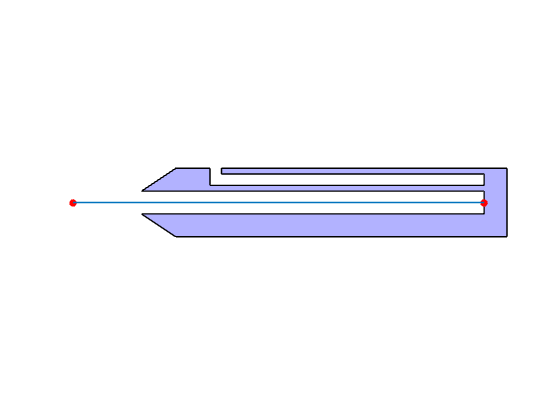

function plotStreamline(dh, v1, v2, rho)
arguments
    dh (1,1) {mustBeReal,mustBeInRange(dh,-20,20)} = 0
    v1 (1,1) {mustBeReal,mustBeGreaterThanOrEqual(v1,0.0)} = 0.0
    v2 (1,1) {mustBeReal,mustBeGreaterThanOrEqual(v2,0.0)} = 0.0
    rho (1,1) {mustBeReal,mustBeGreaterThan(rho,0.0)} = 1000.0
end    

    % Define the path from A to B:
    xl = linspace(0,1,100);
    yl = -dh*(2*xl.^3-3*xl.^2);


    % Create the figure:
    figure
    ax = axes;
    
    % Plot A:
    s = scatter(ax,0,0,30,'filled',SeriesIndex=1);
    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point A:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P = $",  [101325], "%10.0f Pa");

$$u = \left(\begin{array}{c} \frac{1.4142\,\sqrt{\mathrm{pt}-\mathrm{ps}}}{\rho^{0.5000}}\\ -\frac{1.4142\,\sqrt{\mathrm{pt}-\mathrm{ps}}}{\rho^{0.5000}} \end{array}\right)$$

    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$\rho g h = $", [rho*9.81*0], "%10.1f ");
    if v1 > 0.0

$$u = \frac{1.4142\,\sqrt{\mathrm{pt}-\mathrm{ps}}}{\rho^{0.5000}}$$

        s.DataTipTemplate.DataTipRows(4) = dataTipTextRow("$\frac{1}{2}\rho v^2$ = ", [0.5*rho*v1^2], "auto");
    end

$$u = \frac{1.4142\,\sqrt{\mathrm{dp}}}{\rho^{0.5000}}$$

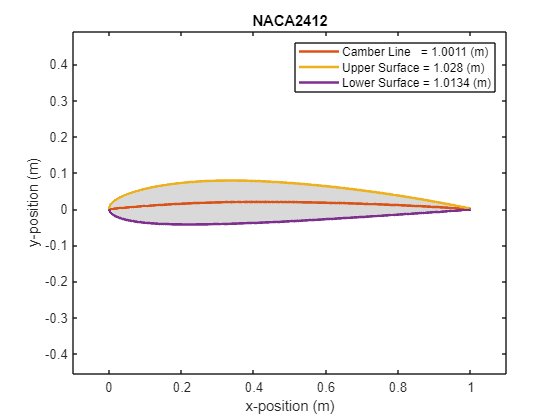

    d = datatip(s);
    d.Interpreter = "latex";
    d.Location = "northwest";
    hold on

    % Plot B:
    s = scatter(ax,1,dh, 'filled',SeriesIndex=1);

    s.DataTipTemplate.DataTipRows    = dataTipTextRow("Point B:", [], "auto");
    s.DataTipTemplate.DataTipRows(2) = dataTipTextRow("$P = ?$",  [], "auto");

$$CruiseSpeed = 69.4500\,\frac{m}{s}$$

    s.DataTipTemplate.DataTipRows(3) = dataTipTextRow("$\rho g h = $", [rho*9.81*dh], "auto");
    if v1 > 0.0
        s.DataTipTemplate.DataTipRows(4) = dataTipTextRow("$\frac{1}{2}\rho v^2$ = ", [0.5*rho*v2^2], "auto");
    end

$$P\_tot = 1.0407e+05\,\frac{\mathrm{kg}}{m\,s^{2}}$$

    d = datatip(s);
    d.Location = "southeast";

$$transitTime = 0.0144\,s$$

    d.Interpreter = "latex";

$$v\_upper = 71.3968\,\frac{m}{s}$$

$$v\_lower = 70.3785\,\frac{m}{s}$$

$$q\_upper = 2.9056e+03\,\frac{\mathrm{kg}}{m\,s^{2}}$$

    % Plot Free Path:

$$P\_upper = 1.0117e+05\,\frac{\mathrm{kg}}{m\,s^{2}}$$

    plot(ax,xl,yl)

$$q\_lower = 2.8233e+03\,\frac{\mathrm{kg}}{m\,s^{2}}$$

    hold off

$$P\_lower = 1.0125e+05\,\frac{\mathrm{kg}}{m\,s^{2}}$$

$$P\_upper = 1.0117e+05\,\frac{\mathrm{kg}}{m\,s^{2}}$$

    % Set plot limit, title, etc.:
    xlim([-0.7 1.7])
    ylim([-22 22])
    title("Flow Streamline from A to B")
    ylabel("Elevation (m)")
    ax.XAxis.Visible = "off";
    
end

function plotPressure()
    figure
    ax = axes;
    axis off
    xlim(ax,[0 1.2])
    ylim(ax,[-1 1])
    l = line(ax,[1 1],[-1 1],"LineWidth",10);
    dt = 0.1;
    x = [0 2*rand-1];
    v = [1 2*rand-1] - x;
    v = v / norm(v);
    
    h = animatedline(ax,'MaximumNumPoints',7,"LineWidth",4,"Color",ax.ColorOrder(5,:));
    addpoints(h, x(1), x(2))
    for i = 1:200
        if l.Color == ax.ColorOrder(3,:)
            l.Color = ax.ColorOrder(1,:);
        end
        x = x + dt*v;
        if x(1) > 1.0
            x(1) = 1.0;
            v(1) = -v(1);
            l.Color = ax.ColorOrder(3,:);
        end
        if x(1) < 0.0
            x = [0 2*rand-1];
            v = [1 2*rand-1] - x;
            v = v / norm(v);
            clearpoints(h)
        end
        addpoints(h, x(1),x(2)) 
        drawnow
    end
end

[⇦ Return to the navigation page](matlab:open('./Overview.html'))